# Designing Filter

## FIR Filtering

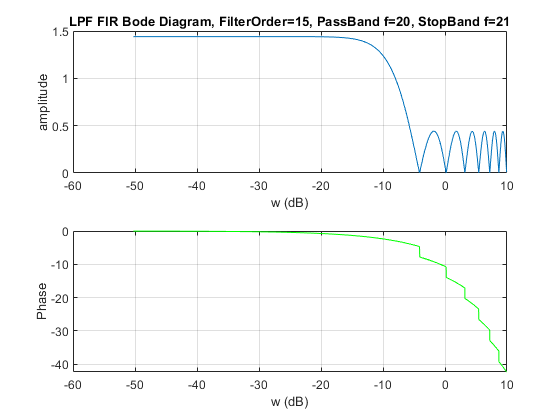

% Designing FIR Low Pass Filter
LPF = designfilt('lowpassfir', ...        % Response type
       'FilterOrder',15, ...            % Filter order
       'PassbandFrequency',20, ...     % Frequency constraints
       'StopbandFrequency',21, ...
       'SampleRate',250);               % Sample rate
   
% Calculating Frequency Response of LPF_ZPS
[h_LPF, w_LPF] = freqz(LPF, 1024);

% Plotting LPF Bode diagram
figure(1)
subplot(2,1,1); plot(db(w_LPF), abs(h_LPF));
title('LPF FIR Bode Diagram, FilterOrder=15, PassBand f=20, StopBand f=21')
xlabel('w (dB)')
ylabel('amplitude')
grid on
subplot(2,1,2); plot(db(w_LPF), phase(h_LPF),'g')
xlabel('w (dB)')
ylabel('Phase')
grid on

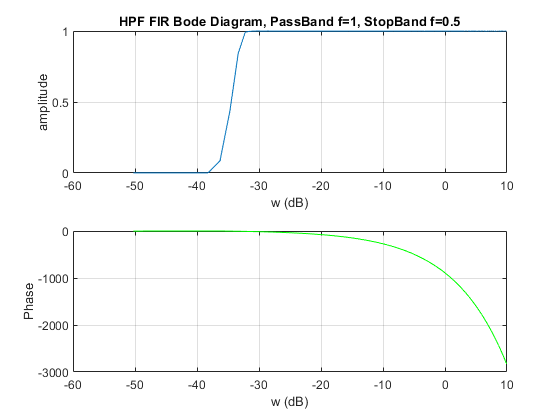


%----------------------------------------------------------
% Designing FIR high Pass Filter
HPF = designfilt('highpassfir', ...       % Response type
       'StopbandFrequency',0.5, ...     % Frequency constraints
       'PassbandFrequency',1, ...
       'PassbandRipple',4, ...    
       'DesignMethod','kaiserwin', ...  % Design method ...
       'SampleRate',250);               % Sample rate
   
% Calculating Frequency Response of LPF_ZPS
[h_HPF, w_HPF] = freqz(HPF,1024);

% Plotting HPF Bode diagram
figure(2)
subplot(2,1,1); plot(db(w_HPF), abs(h_HPF))
title('HPF FIR Bode Diagram, PassBand f=1, StopBand f=0.5')
xlabel('w (dB)')
ylabel('amplitude')
grid on
subplot(2,1,2); plot(db(w_HPF), phase(h_HPF),'g')
xlabel('w (dB)')
ylabel('Phase')
grid on

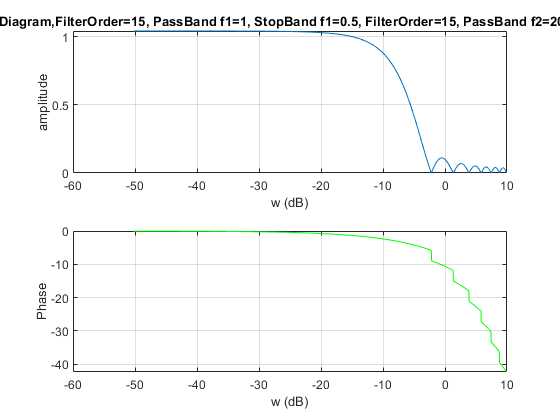


%----------------------------------------------------------
% Designing FIR Band Pass Filter
BPF = designfilt('bandpassfir', ...       % Response type
       'FilterOrder',15, ...            % Filter order
       'StopbandFrequency1',0.5, ...    % Frequency constraints
       'PassbandFrequency1',1, ...
       'PassbandFrequency2',20, ...
       'DesignMethod','ls', ...         % Design method ...
       'StopbandFrequency2',21, ...
       'SampleRate',250);               % Sample rate
   
% Calculating Frequency Response of LPF_ZPS
[h_BPF, w_BPF] = freqz(BPF,1024);

% Plotting HPF Bode diagram
figure(3)
subplot(2,1,1); plot(db(w_BPF), abs(h_BPF))
title('BPF FIR Bode Diagram,FilterOrder=15, PassBand f1=1, StopBand f1=0.5, FilterOrder=15, PassBand f2=20, StopBand f2=21')
xlabel('w (dB)')
ylabel('amplitude')
grid on
subplot(2,1,2); plot(db(w_BPF), phase(h_BPF),'g')
xlabel('w (dB)')
ylabel('Phase')
grid on

## IIR Filtering

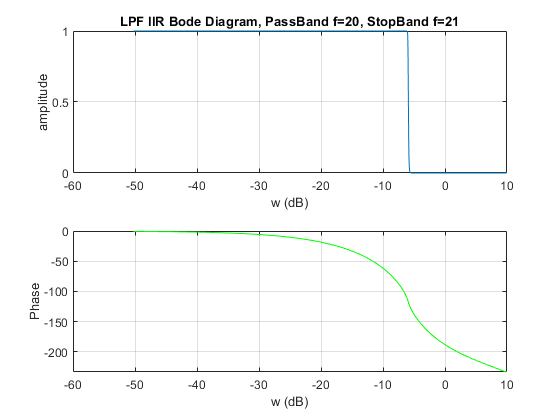

% Designing IIR Low Pass Filter
lpf =  designfilt('lowpassiir', ...        % Response type
       'PassbandFrequency',20, ...     % Frequency constraints
       'StopbandFrequency',21, ...
       'SampleRate',250) ;              % Sample rate

   % Calculating Frequency Response of LPF_ZPS
[h_lpf, w_lpf] = freqz(lpf, 1024);

% Plotting LPF Bode diagram
figure(4)
subplot(2,1,1); plot(db(w_lpf), abs(h_lpf));
title('LPF IIR Bode Diagram, PassBand f=20, StopBand f=21')
xlabel('w (dB)')
ylabel('amplitude')
grid on

subplot(2,1,2); plot(db(w_lpf), phase(h_lpf),'g')
xlabel('w (dB)')
ylabel('Phase')
grid on

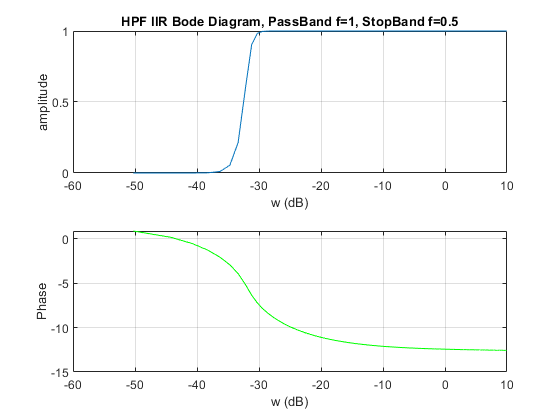


% -----------------------------------------------------------
% Designing IIR high Pass Filter
hpf = designfilt('highpassiir', ...       % Response type
       'StopbandFrequency',0.5, ...     % Frequency constraints
       'PassbandFrequency',1, ...
       'StopbandAttenuation',55, ...    % Magnitude constraints
       'PassbandRipple',4, ...
       'SampleRate',250) ;              % Sample rate
   

% Calculating Frequency Response of LPF_ZPS
[h_hpf, w_hpf] = freqz(hpf,1024);

% Plotting HPF Bode diagram
figure(5)
subplot(2,1,1); plot(db(w_hpf), abs(h_hpf));
title('HPF IIR Bode Diagram, PassBand f=1, StopBand f=0.5');
xlabel('w (dB)');
ylabel('amplitude');
grid on;
subplot(2,1,2); plot(db(w_hpf), phase(h_hpf),'g');
xlabel('w (dB)');
ylabel('Phase');
grid on;

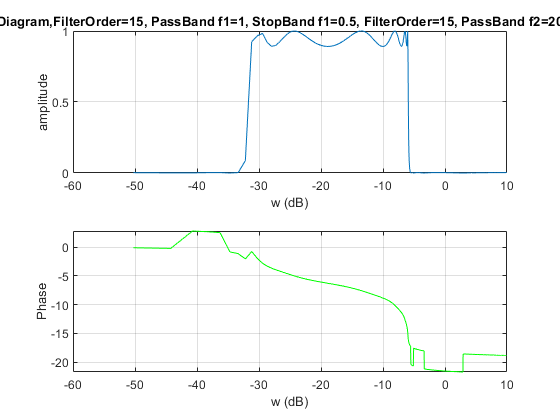


%----------------------------------------------------------
% Designing FIR Band Pass Filter
bpf = designfilt('bandpassiir', ...       % Response type
       'StopbandFrequency1',0.5, ...    % Frequency constraints
       'PassbandFrequency1',1, ...
       'PassbandFrequency2',20, ...
       'StopbandFrequency2',21, ...
       'StopbandAttenuation1',40, ...   % Magnitude constraints
       'PassbandRipple',1, ...
       'StopbandAttenuation2',50, ...
       'DesignMethod','ellip', ...      % Design method
       'MatchExactly','passband', ...   % Design method options
       'SampleRate',250);               % Sample rate
   
% Calculating Frequency Response of LPF_ZPS
[h_bpf, w_bpf] = freqz(bpf,1024);

% Plotting HPF Bode diagram
figure(6)
subplot(2,1,1); plot(db(w_bpf), abs(h_bpf))
title('BPF IIR Bode Diagram,FilterOrder=15, PassBand f1=1, StopBand f1=0.5, FilterOrder=15, PassBand f2=20, StopBand f2=21')
xlabel('w (dB)')
ylabel('amplitude')
grid on
subplot(2,1,2); plot(db(w_bpf), phase(h_bpf),'g')
xlabel('w (dB)')
ylabel('Phase')
grid on